## PREP WORKSPACE

clear all
close all
clc

## LOAD THE DATA

We first load the dataset titled "examgrades"

load examgrades;

## CLEAN AND SUBSET THE DATA

View the dataset and perform necessary cleanup.

%View the first five rows of all columns
grades(1:5,:)

ans =     65    77    69    75    69
    61    74    70    66    68
    81    80    71    74    79
    88    76    80    88    79
    69    77    74    69    76


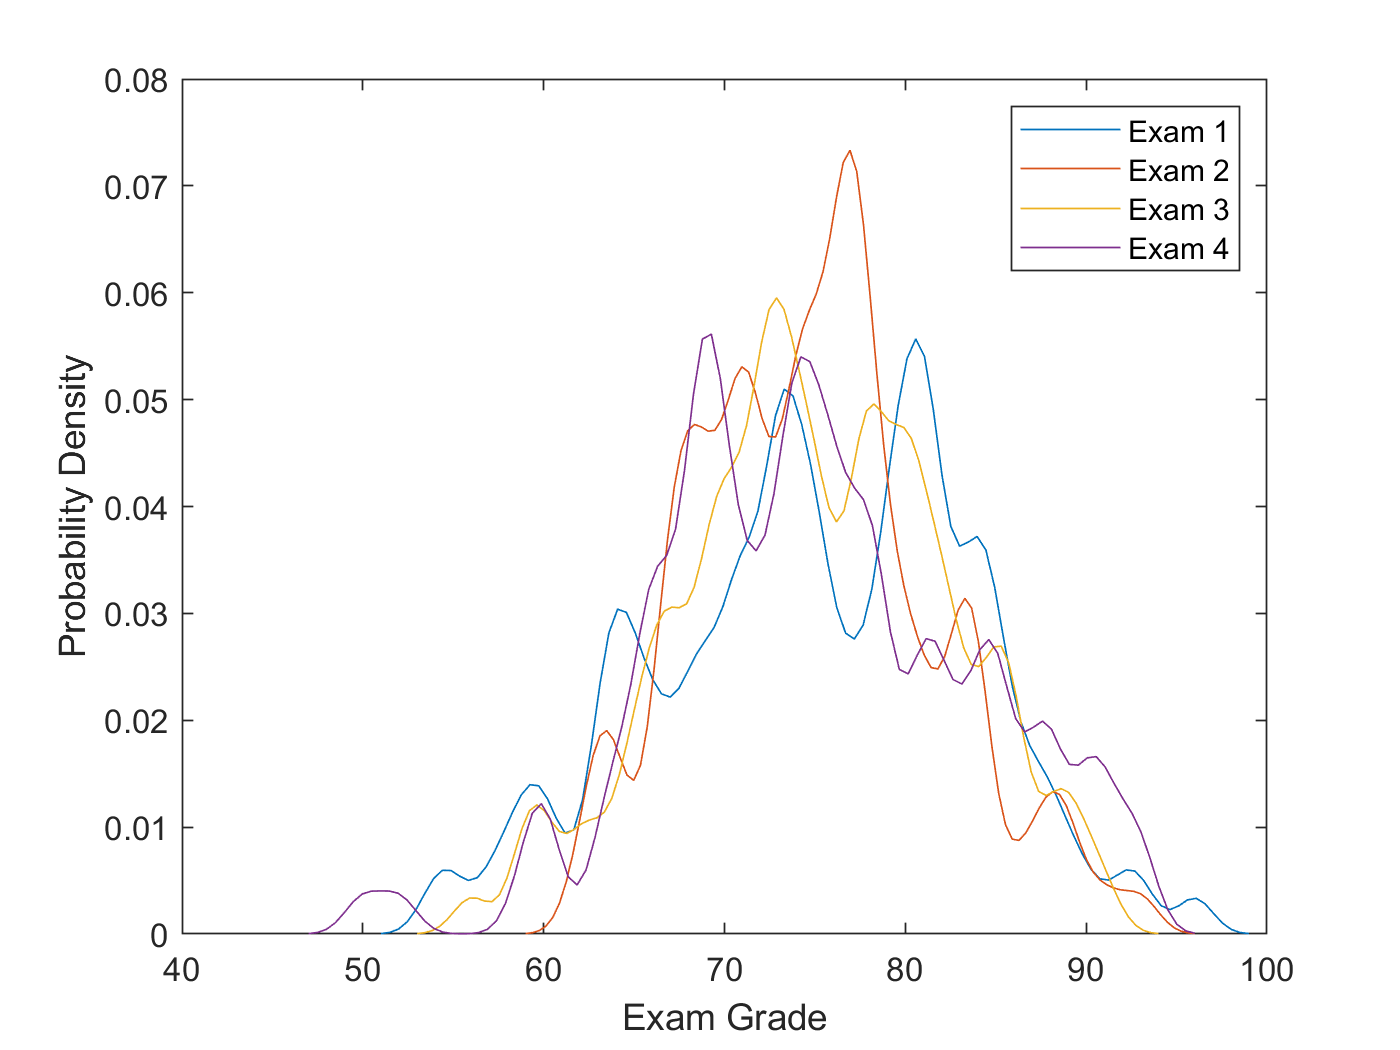

%We only want four columns.
ds = grades(:,1:4);

%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
smthing = 1;
ksdensity(ds(:,1),'Bandwidth',smthing);
hold on
ksdensity(ds(:,2),'Bandwidth',smthing);
ksdensity(ds(:,3),'Bandwidth',smthing);
ksdensity(ds(:,4),'Bandwidth',smthing);
hold off
xlabel('Exam Grade')
ylabel('Probability Density')
legend('Exam 1','Exam 2', 'Exam 3', 'Exam 4')

## Inferential Stats

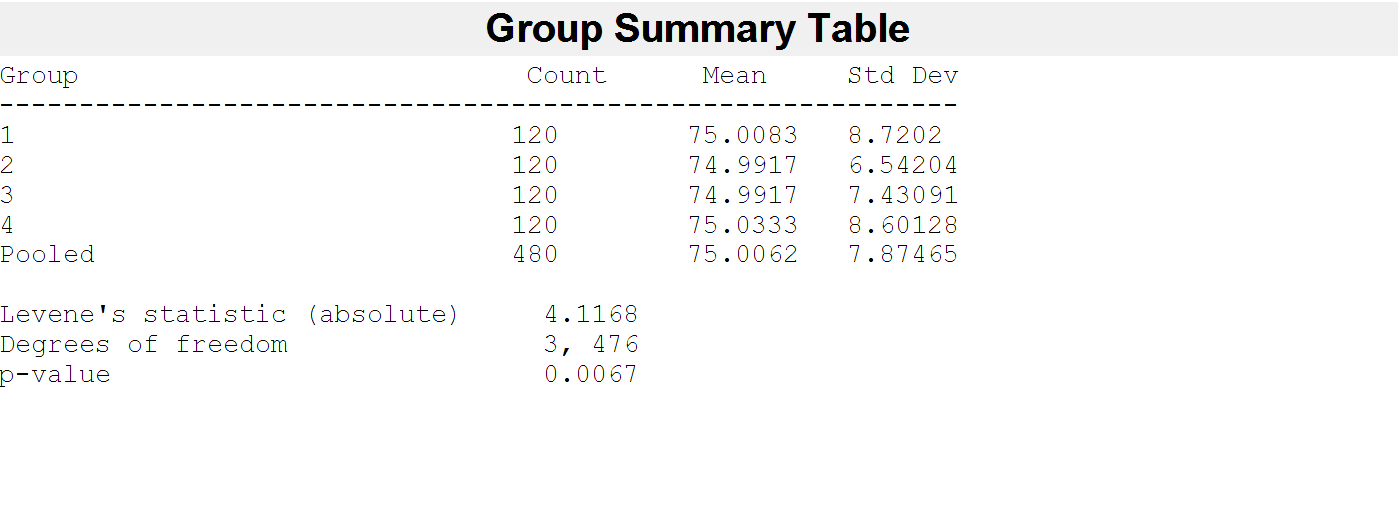

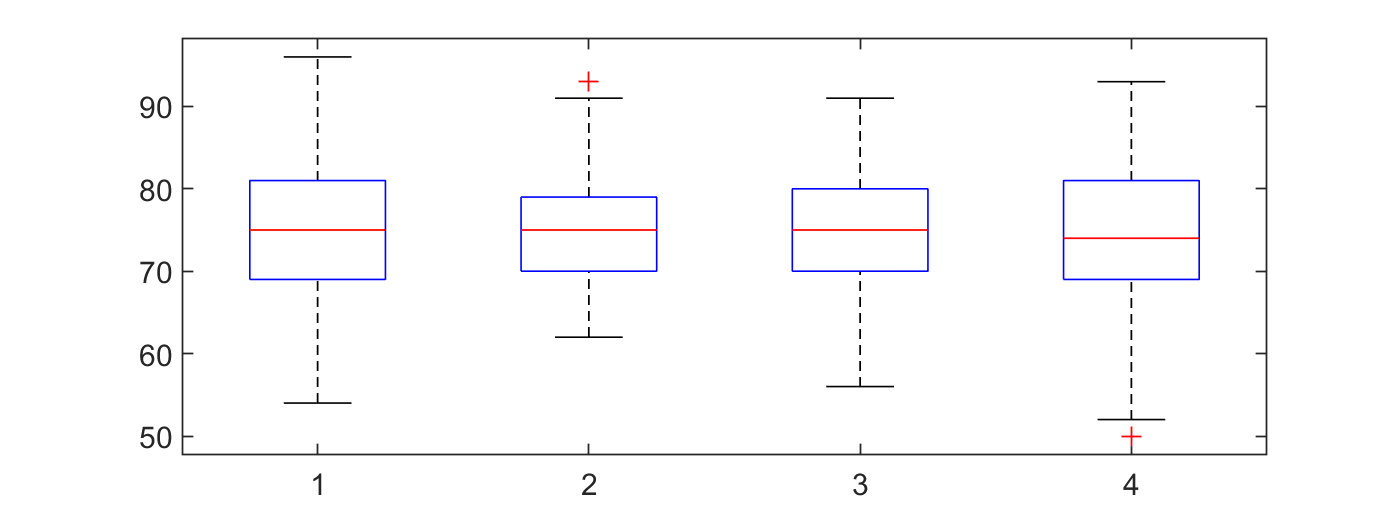

%% SPREAD (VARIANCE) TEST

% multiple sample Levene test for equal variances
% Ho: variances are equal, H1: variances are unequal

[p_var,STATS_var] = vartestn(ds,'TestType','LeveneAbsolute'); 

%% LOCATION (MEANS) TEST: Perform single factor ANOVA
% Single factor ANOVA
% Ho: samples have equal means, H1: samples have unequal means

%wanova needs the data in long format
ds_Long(:,1) = reshape(ds,120*4,1);
ds_Long(:,2) = [linspace(1,1,120)';linspace(2,2,120)';linspace(3,3,120)';linspace(4,4,120)' ];

[p, F, df1, df2] = wanova(ds_Long(:,1),ds_Long(:,2))

p = 1.0000

F = 7.2181e-04

df1 = 3

df2 = 262.7170

%Effect Size (FOR ACADEMIC PURPOSES ONLY)
[stats,varargout]=mes1way(ds_Long(:,1),'omega2','group',ds_Long(:,2))

Unrecognized function or variable 'mes1way'.

## Introduce a Difference


ds(:,1) = ds(:,1) + 15;



%Visual
%'Bandwidth' adjusts how much filtering is applied: larger # = more
%filtering
figure
smthing = 1;
ksdensity(ds(:,1),'Bandwidth',smthing);
hold on
ksdensity(ds(:,2),'Bandwidth',smthing);
ksdensity(ds(:,3),'Bandwidth',smthing);
ksdensity(ds(:,4),'Bandwidth',smthing);
hold off
xlabel('Exam Grade')
ylabel('Probability Density')
legend('Exam 1','Exam 2', 'Exam 3', 'Exam 4')


%% SPREAD (VARIANCE) TEST

% multiple sample Levene test for equal variances
% Ho: variances are equal, H1: variances are unequal

[p_var,STATS_var] = vartestn(ds,'TestType','LeveneAbsolute'); 



%% LOCATION (MEANS) TEST: Perform single factor ANOVA
% Single factor ANOVA
% Ho: samples have equal means, H1: samples have unequal means

%wanova needs the data in long format
ds_Long(:,1) = reshape(ds,120*4,1);
ds_Long(:,2) = [linspace(1,1,120)';linspace(2,2,120)';linspace(3,3,120)';linspace(4,4,120)' ];

[p, F, df1, df2] = wanova(ds_Long(:,1),ds_Long(:,2))
    

%Effect Size
[stats,varargout]=mes1way(ds_Long(:,1),'omega2','group',ds_Long(:,2))

% 65% of the overall variance in our groups can be explained by the
% variances in the means of the groups.

%% POST-HOC ANALYSIS: Perform multiple pairwise comparison tests

% Unequal var = Games and Howell

[h,p,stats]=games_howell(ds_Long(:,1),ds_Long(:,2))



## POINT AND INTERVAL ESTIMATES

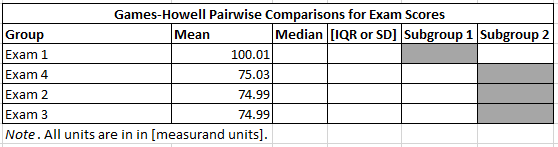

mean(ds)